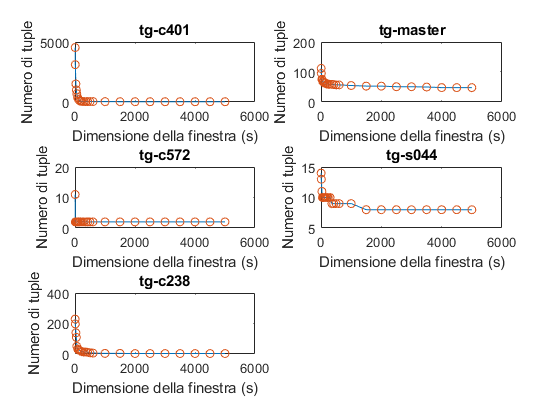

%tg-c401
CWIN = [5 
10 
30 
45 
60
90
120
160
200
240
300
360
420
500
600
1000
1500
2000
2500
3000
3500
4000
4500
5000];
n_tuple_mercury = [4541
3113
1504
1004
 693
 369
 207
 97
 59
 48
 40
 37
 37
 37
 37
 31
 25
 25
 24
 24
 24
 24
 24
 24];
subplot(3,2,1);
plot(CWIN,n_tuple_mercury,CWIN,n_tuple_mercury,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('tg-c401')
%tg-master
n_tuple_bgl=[112
95
76
73
68
66
63
63
60
59
59
59
58
57
57
55
53
53
51
51
50
48
48
48];
subplot(3,2,2);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('tg-master')
%tg-c572
n_tuple_bgl=[11
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2
2];
subplot(3,2,3);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('tg-c572')
%tg-s044
n_tuple_bgl=[14
13
11
10
10
10
10
10
10
10
10
9
9
9
9
9
8
8
8
8
8
8
8
8];
subplot(3,2,4);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('tg-s044')
%tg-c238
n_tuple_bgl=[229
197
139
109
50
32
27
23
18
15
13
13
11
8
6
4
4
3
3
3
3
3
3
3];
subplot(3,2,5);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('tg-c238')
saveas(gcf,'tupleCountMercury-nodes','png');

clf

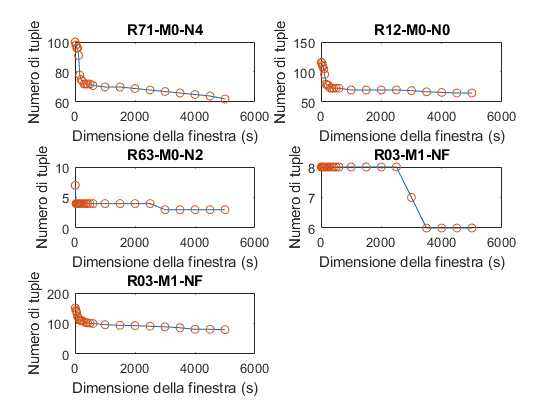

%R71-M0-N4
CWIN = [5 
10 
30 
45 
60
90
120
160
200
240
300
360
420
500
600
1000
1500
2000
2500
3000
3500
4000
4500
5000];
n_tuple_mercury = [100
100
98
98
96
96
91
78
75
74
72
72
72
72
71
70
70
69
68
67
66
65
64
62];
subplot(3,2,1);
plot(CWIN,n_tuple_mercury,CWIN,n_tuple_mercury,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('R71-M0-N4')
%R12-M0-N0
n_tuple_bgl=[116
116
115
111
109
105
96
80
78
78
73
73
73
73
73
70
70
70
70
69
67
66
65
65];
subplot(3,2,2);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('R12-M0-N0')
%R63-M0-N2
n_tuple_bgl=[7
7
4
4
4
4
4
4
4
4
4
4
4
4
4
4
4
4
4
3
3
3
3
3];
subplot(3,2,3);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('R63-M0-N2')
%R03-M1-NF
n_tuple_bgl=[8
8
8
8
8
8
8
8
8
8
8
8
8
8
8
8
8
8
8
7
6
6
6
6];
subplot(3,2,4);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('R03-M1-NF')
%R63-M0-N0
n_tuple_bgl=[151
151
143
139
135
123
117
110
109
109
106
103
102
101
100
96
94
93
91
89
86
81
81
80];
subplot(3,2,5);
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'o')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
title('R03-M1-NF')
saveas(gcf,'tupleCountBLG-nodes','png');

clf

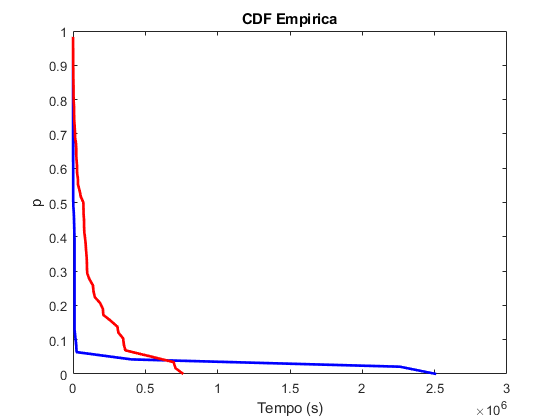

id = fopen("C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\5\design\ffdatoolsetIE2016\mercuryFiltratoNodi\tupling_tg-c401-MercuryErrorLog-240\interarrivals.txt");
intarrivals = fscanf(id,'%d');
[p,t]=cdfcalc(intarrivals);
ttf=p(2:size(p,1));
rel = 1-ttf;

id2 = fopen("C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\5\design\ffdatoolsetIE2016\mercuryFiltratoNodi\tupling_tg-master-MercuryErrorLog-240\interarrivals.txt");
intarrivals2 = fscanf(id2,'%d');
[p2,t2]=cdfcalc(intarrivals2);
ttf2=p2(2:size(p2,1));
rel2 = 1-ttf2;

plot(t,rel,'b',t2,rel2,'r','LineWidth',2);
xlabel('Tempo (s)')
ylabel('p')
title('CDF Empirica');
saveas(gcf,'cdfEmpiricaMercury-nodes','png');

clf

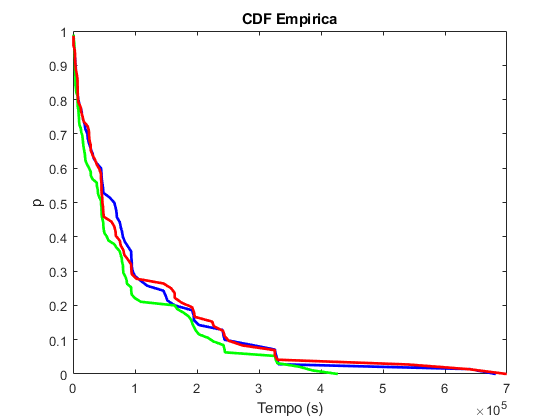

id = fopen("C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\5\design\ffdatoolsetIE2016\bglFiltratoNodi\tupling_R71-M0-N4-BGLErrorLog-600\interarrivals.txt");
intarrivals = fscanf(id,'%d');
[p,t]=cdfcalc(intarrivals);
ttf=p(2:size(p,1));
rel = 1-ttf;

id2 = fopen("C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\5\design\ffdatoolsetIE2016\bglFiltratoNodi\tupling_R63-M0-N0-BGLErrorLog-1000\interarrivals.txt");
intarrivals2 = fscanf(id2,'%d');
[p2,t2]=cdfcalc(intarrivals2);
ttf2=p2(2:size(p2,1));
rel2 = 1-ttf2;

id3 = fopen("C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\5\design\ffdatoolsetIE2016\bglFiltratoNodi\tupling_R12-M0-N0-BGLErrorLog-600\interarrivals.txt");
intarrivals3 = fscanf(id3,'%d');
[p3,t3]=cdfcalc(intarrivals3);
ttf3=p3(2:size(p3,1));
rel3 = 1-ttf3;

plot(t,rel,'b',t2,rel2,'g',t3,rel3,'r','LineWidth',2);
xlabel('Tempo (s)')
ylabel('p')
title('CDF Empirica');
saveas(gcf,'cdfEmpiricaBGL-nodes','png');

clf